In this demo, we set the flow velocity to be 5.75, where the pipe system is under flutter. This pipe system has asymmetric stiffness and damping matrices, and hence is a general dynamical system. We construct a 2D unstable SSM around the unstable straight configuration. We expect there exists a stable limit cycle on the SSM. More details can be found in [1]

[1] M. Li, H. Yan, L. Wang: Nonlinear model reduction for a cantilevered pipe conveying fluid: A system with asymmetric damping and stiffness matrices. MSSP. 2023. [https://doi.org/10.1016/j.ymssp.2022.109993](https://doi.org/10.1016/j.ymssp.2022.109993)

### Create dynamical model

clear all;
nmodes = 4;
fcload = 1;
flowspeed = 5.75;
alpha=0.001;
beta=0.2;
[M, C, K, fnl,fext,DM,DC,DK,dfnl2,dfnl3,dfext] = build_model_semi(nmodes,flowspeed,beta,alpha,'clamped-free');

Getting linear and nonlinearity coefficients
Loaded coefficients from storage


DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl_semi',fnl,'nl_damp',true);
set(DS.Options,'Emax',10,'Nmax',10,'notation','multiindex');
set(DS.Options,'RayleighDamping',false);
set(DS,'DM',DM,'DC',DC,'DK',DK);
set(DS,'Dfnl2_semi',dfnl2,'Dfnl3_semi',dfnl3);
[V,D,W] = DS.linear_spectral_analysis();


 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0022 + 0.1354i
   0.0022 - 0.1354i
  -0.0687 + 0.4875i
  -0.0687 - 0.4875i
  -0.1118 + 0.0292i
  -0.1118 - 0.0292i
  -0.1221 + 1.1069i
  -0.1221 - 1.1069i



Om = 13.5;
set(DS,'fext',fext,'Omega',Om,'dfext',dfext);

### SSM computation - explicit computation

S = SSM(DS);
resonant_modes = [1 2]; % choose master spectral subspace
S.choose_E(resonant_modes);

sigma_out = -54
sigma_in = -54


%% explicit computation
[We,Re] = S.explicit_whisker();


 second order explict solution 


### SSM computation - via SSMTool parameterization

[W_0,R_0,W_1,R_1] = ssmtool_comp(nmodes,flowspeed,beta,alpha,Om);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0022 + 0.1354i
   0.0022 - 0.1354i
  -0.0687 + 0.4875i
  -0.0687 - 0.4875i
  -0.1118 + 0.0292i
  -0.1118 - 0.0292i
  -0.1221 + 1.1069i
  -0.1221 - 1.1069i

sigma_out = -54
sigma_in = -54
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.19E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.37E-02 MB


### SSM senstivity computation

[DW,DR] = S.explicit_senstivity_whisker(We,Re);
DW10 = DW.DW10; DW20 = DW.DW20; DW11 = DW.DW11;
DW30 = DW.DW30; DW21 = DW.DW21; Dx0 = DW.Dx0;
Dlamd = DR.Dlamd; Dr21 = DR.Dr21;
Dom = DR.Dom; Dpsi = DR.Dpsi; Dftilde = DR.Dftilde;

### Comparison of SSM results 

#### Explicit solution and SSMTool solution

fprintf('\n difference in terms of W10 \n')


 difference in terms of W10 


norm(We.W10-full(W_0(1).coeffs(:,2)))/norm(We.W10)

ans = 8.5042e-14

fprintf('\n W2 are all zeros \n')


 W2 are all zeros 


W_0(2)

ans = struct with fields:
    coeffs: [8×0 double]
       ind: [0×2 double]


[We.W20 We.W11]

ans =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


fprintf('\n difference in terms of W30 \n')


 difference in terms of W30 


norm(We.W30-full(W_0(3).coeffs(:,4)))/norm(We.W30)

ans = 1.1832e-15

fprintf('\n difference in terms of W21 \n')


 difference in terms of W21 


norm(We.W21-full(W_0(3).coeffs(:,3)))/norm(We.W21)

ans = 1.4811e-10

fprintf('\n difference in terms of x0 \n')


 difference in terms of x0 


W_1(2).kappa

ans = 1

norm(We.x0-W_1(2).W.coeffs)/norm(We.x0)

ans = 6.9456e-12

fprintf('\n difference in terms of gamma \n')


 difference in terms of gamma 


abs(Re.r21-full(R_0(3).coeffs(1,2)))/abs(Re.r21)

ans = 6.4432e-16

fprintf('\n difference in terms of ftilde \n')


 difference in terms of ftilde 


abs(Re.ftilde-R_1(2).R.coeffs(1))/abs(Re.ftilde)

ans = 2.1786e-17

### Compare results - sensitivity of SSM. (Explicit vs central finite difference)

#### Derivatives w.r.t $u$

% Finite difference solutions
uE  = DS.spectrum.W(:,1);
psi = conj(uE(1:DS.n)); lo = (2*D(1)*M+C).'*psi;
du = 0.001*flowspeed;
% compute perturbed SSMs
ssm_up = comp_ssm(nmodes,flowspeed+du,beta,alpha,lo,Om);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0023 + 0.1353i
   0.0023 - 0.1353i
  -0.0687 + 0.4872i
  -0.0687 - 0.4872i
  -0.1121 + 0.0290i
  -0.1121 - 0.0290i
  -0.1221 + 1.1067i
  -0.1221 - 1.1067i



ans =    1.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


ans = 1.0e-11 *

  -0.1079 - 0.0430i  -0.0524 + 0.0345i
  -0.0524 - 0.0345i  -0.1079 + 0.0430i


sigma_out = -52
sigma_in = -52

 second order explict solution 


ssm_um = comp_ssm(nmodes,flowspeed-du,beta,alpha,lo,Om);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0021 + 0.1354i
   0.0021 - 0.1354i
  -0.0686 + 0.4878i
  -0.0686 - 0.4878i
  -0.1116 + 0.0294i
  -0.1116 - 0.0294i
  -0.1220 + 1.1072i
  -0.1220 - 1.1072i



ans =    1.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


ans = 1.0e-12 *

  -0.8269 - 0.4974i  -0.3768 + 0.2887i
  -0.3768 - 0.2887i  -0.8269 + 0.4974i


sigma_out = -58
sigma_in = -58

 second order explict solution 


% Calculate derivatives
dw10_du = (ssm_up.W10-ssm_um.W10)/(2*du);
dw20_du = (ssm_up.W20-ssm_um.W20)/(2*du);
dw11_du = (ssm_up.W11-ssm_um.W11)/(2*du);
dw30_du = (ssm_up.W30-ssm_um.W30)/(2*du);
dw21_du = (ssm_up.W21-ssm_um.W21)/(2*du);
dlam_du = (ssm_up.lamd-ssm_um.lamd)/(2*du);
dr21_du = (ssm_up.r21-ssm_um.r21)/(2*du);
dpsi_du = (ssm_up.psi-ssm_um.psi)/(2*du);
dx0_du  = (ssm_up.x0-ssm_um.x0)/(2*du);
dftilde_du = (ssm_up.ftilde-ssm_um.ftilde)/(2*du);

% compute relative or absolute errors and print them 
fprintf('relative error for dw10_du is %d\n', norm(DW10(:,1)-dw10_du)/norm(DW10(:,1))); 

relative error for dw10_du is 5.469299e-06


fprintf('absolute error for dw20_du is %d\n', norm(DW20(:,1)-dw20_du)); 

absolute error for dw20_du is 0


fprintf('absolute error for dw11_du is %d\n', norm(DW11(:,1)-dw11_du)); 

absolute error for dw11_du is 0


fprintf('relative error for dw30_du is %d\n', norm(DW30(:,1)-dw30_du)/norm(DW30(:,1))); 

relative error for dw30_du is 8.693302e-06


fprintf('relative error for dw21_du is %d\n', norm(DW21(:,1)-dw21_du)/norm(DW21(:,1))); 

relative error for dw21_du is 3.026210e-05


fprintf('relative error for dlamd_du is %d\n', norm(Dlamd(1)-dlam_du)/norm(Dlamd(1))); 

relative error for dlamd_du is 1.903660e-06


fprintf('relative error for dr21_du is %d\n', norm(Dr21(1)-dr21_du)/norm(Dr21(1)));

relative error for dr21_du is 1.002168e-05


fprintf('relative error for dpsi_du is %d\n', norm(Dpsi(:,1)-dpsi_du)/norm(Dpsi(:,1)));

relative error for dpsi_du is 1.109922e-05


fprintf('relative error for dx0_du is %d\n', norm(Dx0(:,1)-dx0_du)/norm(Dx0(:,1)));

relative error for dx0_du is 1.782362e-05


fprintf('relative error for dftilde_du is %d\n', norm(Dftilde(1)-dftilde_du)/norm(Dftilde(1)));

relative error for dftilde_du is 1.413412e-05


#### Derivatives w.r.t $\beta$

% computation of peturbed SSMs
dbe = 0.001*beta; 
ssm_bep = comp_ssm(nmodes,flowspeed,beta+dbe,alpha,lo,Om);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0022 + 0.1354i
   0.0022 - 0.1354i
  -0.0687 + 0.4875i
  -0.0687 - 0.4875i
  -0.1118 + 0.0292i
  -0.1118 - 0.0292i
  -0.1221 + 1.1070i
  -0.1221 - 1.1070i



ans =    1.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


ans = 1.0e-11 *

  -0.1014 - 0.0389i  -0.0458 + 0.0357i
  -0.0458 - 0.0357i  -0.1014 + 0.0389i


sigma_out = -56
sigma_in = -56

 second order explict solution 


ssm_bem = comp_ssm(nmodes,flowspeed,beta-dbe,alpha,lo,Om);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0023 + 0.1354i
   0.0023 - 0.1354i
  -0.0686 + 0.4875i
  -0.0686 - 0.4875i
  -0.1118 + 0.0292i
  -0.1118 - 0.0292i
  -0.1220 + 1.1069i
  -0.1220 - 1.1069i



ans =    1.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


ans = 1.0e-12 *

  -0.9358 - 0.6111i  -0.4501 + 0.3277i
  -0.4501 - 0.3277i  -0.9358 + 0.6111i


sigma_out = -53
sigma_in = -53

 second order explict solution 


% calculate derivatives
dw10_dbe = (ssm_bep.W10-ssm_bem.W10)/(2*dbe);
dw20_dbe = (ssm_bep.W20-ssm_bem.W20)/(2*dbe);
dw11_dbe = (ssm_bep.W11-ssm_bem.W11)/(2*dbe);
dw30_dbe = (ssm_bep.W30-ssm_bem.W30)/(2*dbe);
dw21_dbe = (ssm_bep.W21-ssm_bem.W21)/(2*dbe);
dlam_dbe = (ssm_bep.lamd-ssm_bem.lamd)/(2*dbe);
dr21_dbe = (ssm_bep.r21-ssm_bem.r21)/(2*dbe);
dpsi_dbe = (ssm_bep.psi-ssm_bem.psi)/(2*dbe);
dx0_dbe  = (ssm_bep.x0-ssm_bem.x0)/(2*dbe);
dftilde_dbe = (ssm_bep.ftilde-ssm_bem.ftilde)/(2*dbe);

% compute relative or absolute errors and print them
fprintf('relative error for dw10_dbe is %d\n', norm(DW10(:,2)-dw10_dbe)/norm(DW10(:,2))); 

relative error for dw10_dbe is 1.225966e-07


fprintf('absolute error for dw20_dbe is %d\n', norm(DW20(:,2)-dw20_dbe)); 

absolute error for dw20_dbe is 0


fprintf('absolute error for dw11_dbe is %d\n', norm(DW11(:,2)-dw11_dbe)); 

absolute error for dw11_dbe is 0


fprintf('relative error for dw30_dbe is %d\n', norm(DW30(:,2)-dw30_dbe)/norm(DW30(:,2))); 

relative error for dw30_dbe is 1.349836e-06


fprintf('relative error for dw21_dbe is %d\n', norm(DW21(:,2)-dw21_dbe)/norm(DW21(:,2))); 

relative error for dw21_dbe is 6.345857e-07


fprintf('relative error for dlamd_dbe is %d\n', norm(Dlamd(2)-dlam_dbe)/norm(Dlamd(2))); 

relative error for dlamd_dbe is 1.151730e-07


fprintf('relative error for dr21_dbe is %d\n', norm(Dr21(2)-dr21_dbe)/norm(Dr21(2)));

relative error for dr21_dbe is 1.168884e-07


fprintf('relative error for dpsi_dbe is %d\n', norm(Dpsi(:,2)-dpsi_dbe)/norm(Dpsi(2)));

relative error for dpsi_dbe is 5.459802e-07


fprintf('relative error for dx0_dbe is %d\n', norm(Dx0(:,2)-dx0_dbe)/norm(Dx0(:,2)));

relative error for dx0_dbe is 2.621111e-07


fprintf('relative error for dftilde_dbe is %d\n', norm(Dftilde(2)-dftilde_dbe)/norm(Dftilde(2)));

relative error for dftilde_dbe is 1.418935e-07


#### Derivatives w.r.t $\alpha$

% computation of peturbed SSMs
dal = 0.01*alpha;
ssm_alp = comp_ssm(nmodes,flowspeed,beta,alpha+dal,lo,Om);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0022 + 0.1353i
   0.0022 - 0.1353i
  -0.0689 + 0.4875i
  -0.0689 - 0.4875i
  -0.1118 + 0.0292i
  -0.1118 - 0.0292i
  -0.1228 + 1.1069i
  -0.1228 - 1.1069i



ans =    1.0000 + 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 - 0.0000i


ans = 1.0e-11 *

  -0.1109 - 0.0300i  -0.0515 + 0.0331i
  -0.0515 - 0.0331i  -0.1109 + 0.0300i


sigma_out = -55
sigma_in = -55

 second order explict solution 


ssm_alm = comp_ssm(nmodes,flowspeed,beta,alpha-dal,lo,Om);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0022 + 0.1354i
   0.0022 - 0.1354i
  -0.0685 + 0.4875i
  -0.0685 - 0.4875i
  -0.1118 + 0.0292i
  -0.1118 - 0.0292i
  -0.1213 + 1.1070i
  -0.1213 - 1.1070i



ans =    1.0000 + 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


ans = 1.0e-12 *

  -0.8240 - 0.7230i  -0.4956 + 0.3304i
  -0.4956 - 0.3304i  -0.8240 + 0.7230i


sigma_out = -54
sigma_in = -54

 second order explict solution 


% calculate derivatives
dw10_dal = (ssm_alp.W10-ssm_alm.W10)/(2*dal);
dw20_dal = (ssm_alp.W20-ssm_alm.W20)/(2*dal);
dw11_dal = (ssm_alp.W11-ssm_alm.W11)/(2*dal);
dw30_dal = (ssm_alp.W30-ssm_alm.W30)/(2*dal);
dw21_dal = (ssm_alp.W21-ssm_alm.W21)/(2*dal);
dlam_dal = (ssm_alp.lamd-ssm_alm.lamd)/(2*dal);
dr21_dal = (ssm_alp.r21-ssm_alm.r21)/(2*dal);
dpsi_dal = (ssm_alp.psi-ssm_alm.psi)/(2*dal);
dx0_dal  = (ssm_alp.x0-ssm_alm.x0)/(2*dal);
dftilde_dal = (ssm_alp.ftilde-ssm_alm.ftilde)/(2*dal);

% compute relative or absolute errors and print them
fprintf('relative error for dw10_dal is %d\n', norm(DW10(:,3)-dw10_dal)/norm(DW10(:,3))); 

relative error for dw10_dal is 2.389868e-08


fprintf('absolute error for dw20_dal is %d\n', norm(DW20(:,3)-dw20_dal)); 

absolute error for dw20_dal is 0


fprintf('absolute error for dw11_dal is %d\n', norm(DW11(:,3)-dw11_dal)); 

absolute error for dw11_dal is 0


fprintf('relative error for dw30_dal is %d\n', norm(DW30(:,3)-dw30_dal)/norm(DW30(:,3))); 

relative error for dw30_dal is 1.804026e-06


fprintf('relative error for dw21_dal is %d\n', norm(DW21(:,3)-dw21_dal)/norm(DW21(:,3))); 

relative error for dw21_dal is 7.283591e-08


fprintf('relative error for dlamd_dal is %d\n', norm(Dlamd(3)-dlam_dal)/norm(Dlamd(3))); 

relative error for dlamd_dal is 2.154253e-08


fprintf('relative error for dr21_dal is %d\n', norm(Dr21(3)-dr21_dal)/norm(Dr21(3)));

relative error for dr21_dal is 7.775720e-08


fprintf('relative error for dpsi_dal is %d\n', norm(Dpsi(:,3)-dpsi_dal)/norm(Dpsi(:,3)));

relative error for dpsi_dal is 4.061107e-08


fprintf('relative error for dx0_dal is %d\n', norm(Dx0(:,3)-dx0_dal)/norm(Dx0(:,3)));

relative error for dx0_dal is 7.628063e-08


fprintf('relative error for dftilde_dal is %d\n', norm(Dftilde(3)-dftilde_dal)/norm(Dftilde(3)));

relative error for dftilde_dal is 4.213638e-08


#### Curvature of SSM

% calculate curvature
Curv = We.W20'*We.W20+We.W11'*We.W11

Curv = 0

% derivatives of curvature
DCurv = 2*real(We.W20'*DW.DW20)+2*(We.W11'*DW.DW11)

DCurv =      0     0     0


### Perturbed SSM and backbone curves

- **Perturbed SSM**

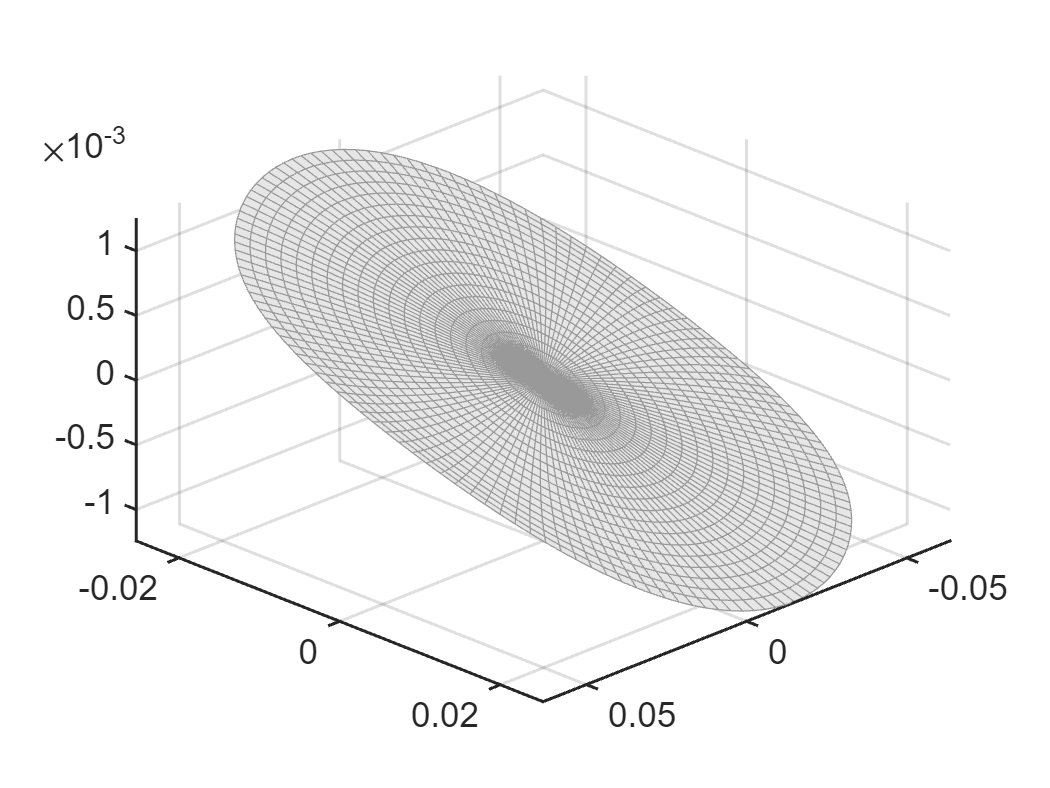

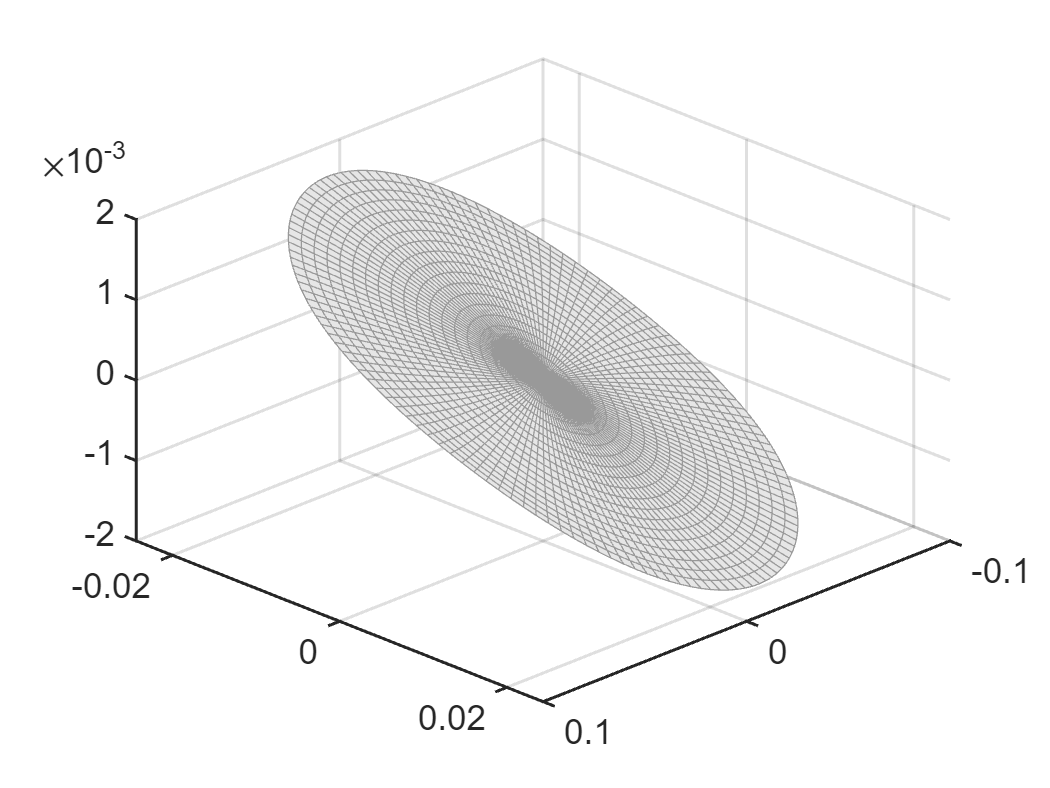

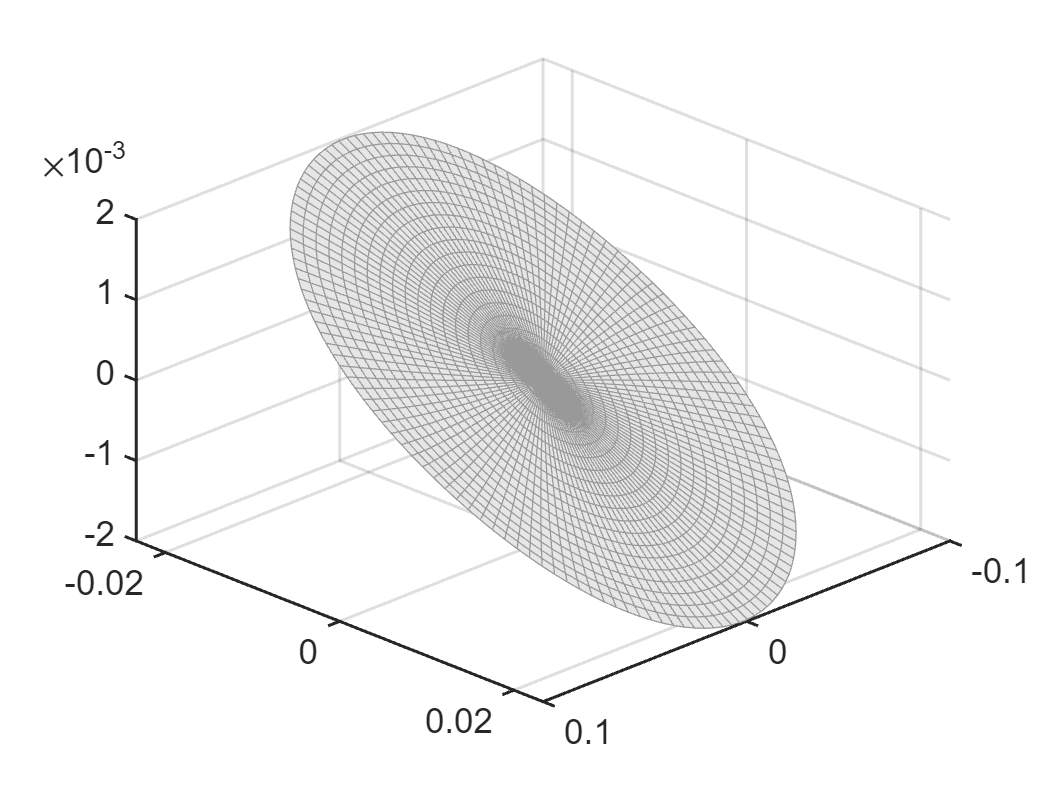

pidx = 1;
rhosamp = linspace(0,0.6,21); plotdof = [1 2 3]; pfracs = [-0.3 0 0.3];
zmesh = S.SSM_sensitivity(We,DW,rhosamp,plotdof,pidx,pfracs);

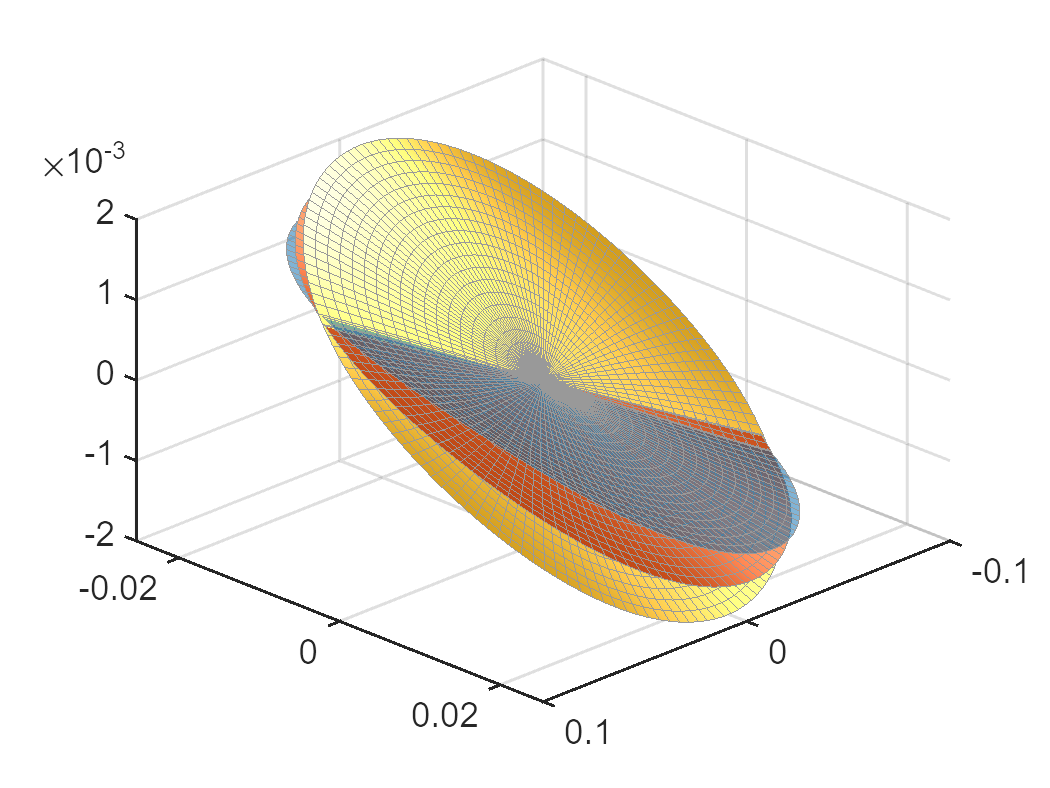

colors = get(0,'defaultaxescolororder');
figure; hold on
h = surf(zmesh{1}.zdof1,zmesh{1}.zdof2,zmesh{1}.zdof3,'FaceColor', colors(1,:), 'FaceAlpha', 0.5, ...
    'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.2);
view([1,1,1])
grid on
set(gca,'LineWidth',1.2);
set(gca,'FontSize',14);

surf(zmesh{2}.zdof1,zmesh{2}.zdof2,zmesh{2}.zdof3,'FaceColor', colors(2,:), 'FaceAlpha', 1, ...
    'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.2);
surf(zmesh{3}.zdof1,zmesh{3}.zdof2,zmesh{3}.zdof3,'FaceColor', colors(3,:), 'FaceAlpha', 1, ...
    'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.2);
camlight; lighting gouraud

- **Backbone curves**

outdof = [1 2];
freqRange = [13 14.5];
% pidx   = 1; pfracs = [-0.015 0 0.015]*flowspeed;
% pidx   = 2; pfracs = [-0.08 0 0.08]*beta;
pidx   = 3; pfracs = [-1 0 1]*alpha;
phiend = zeros(nmodes,1);
lamda = [1.875104068711961
   4.694091132974175
   7.854757438237613
  10.995540734875467
  14.137168391046471
  17.278759532088237
  20.420352251041251
  23.561944901806445];
for k=1:nmodes
   x    = 1;
   phin = cos(lamda(k)*x)-cosh(lamda(k)*x)-(cos(lamda(k))+cosh(lamda(k)))/(sin(lamda(k))+sinh(lamda(k)))*...
        (sin(lamda(k)*x)-sinh(lamda(k)*x));%clamped-free
   phiend(k) = phin;
end
% disp at the free end
obsfun = @(x,mapx) mapx*x;
Mapmat = [phiend' zeros(1,nmodes); zeros(1,nmodes) phiend'];
obs = @(x) obsfun(x,Mapmat);
pBBs = S.BB_sensitivity(We,Re,DW,DR,obs,freqRange,pidx,pfracs);

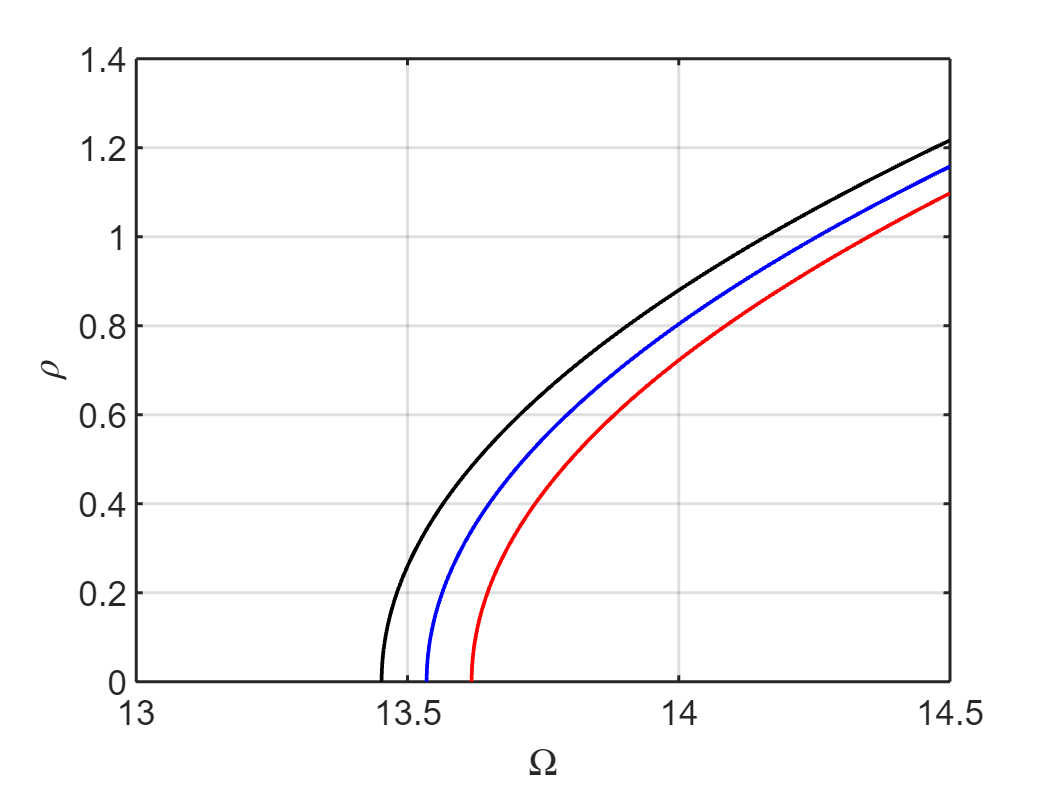

% plot results
figure; hold on
plot(pBBs{1}.om,pBBs{1}.rho,'r-','LineWidth',1.5);
plot(pBBs{2}.om,pBBs{2}.rho,'b-','LineWidth',1.5)
plot(pBBs{3}.om,pBBs{3}.rho,'k-','LineWidth',1.5)
grid on; box on; xlim(freqRange);
xlabel('$\Omega$','FontSize',14,'Interpreter','latex');
ylabel('$\rho$','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',14);
set(gca,'LineWidth',1.2);

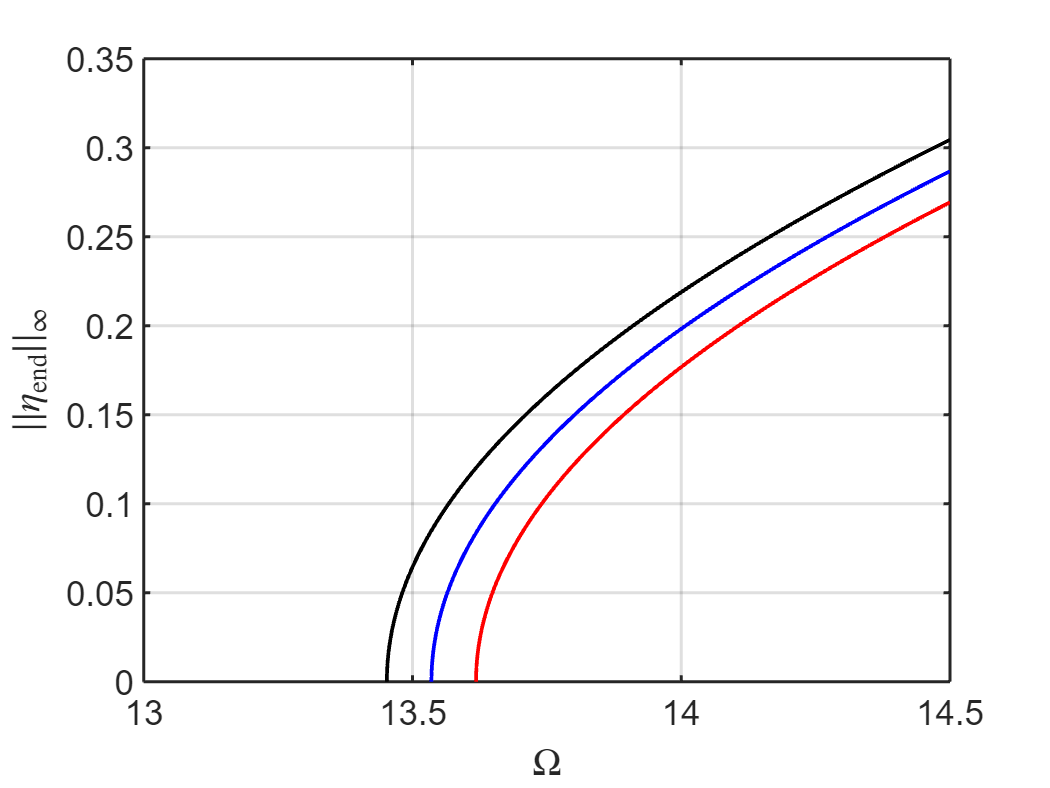

figrho = gcf;

figure; hold on
plot(pBBs{1}.om,pBBs{1}.ampLinf(1,:),'r-','LineWidth',1.5);
plot(pBBs{2}.om,pBBs{2}.ampLinf(1,:),'b-','LineWidth',1.5)
plot(pBBs{3}.om,pBBs{3}.ampLinf(1,:),'k-','LineWidth',1.5)
grid on; box on; xlim(freqRange);
xlabel('$\Omega$','FontSize',14,'Interpreter','latex');
ylabel('$||\eta_\mathrm{end}||_\infty$','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',14);
set(gca,'LineWidth',1.2);

figz = gcf;

- **Direct computation - for the purpose of validation**

% bbp1 = comp_bb(nmodes,flowspeed+pfracs(1),beta,alpha,lo,obs,freqRange);
% bbp3 = comp_bb(nmodes,flowspeed+pfracs(3),beta,alpha,lo,obs,freqRange);
% bbp1 = comp_bb(nmodes,flowspeed,beta+pfracs(1),alpha,lo,obs,freqRange);
% bbp3 = comp_bb(nmodes,flowspeed,beta+pfracs(3),alpha,lo,obs,freqRange);
bbp1 = comp_bb(nmodes,flowspeed,beta,alpha+pfracs(1),lo,obs,freqRange);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0033 + 0.1362i
   0.0033 - 0.1362i
  -0.0484 + 1.1129i
  -0.0484 - 1.1129i
  -0.0498 + 0.4900i
  -0.0498 - 0.4900i
  -0.1107 + 0.0302i
  -0.1107 - 0.0302i



ans =    1.0000 + 0.0000i  -0.0000 + 0.0000i
  -0.0000 - 0.0000i   1.0000 - 0.0000i


ans = 1.0e-11 *

  -0.0987 + 0.1400i  -0.0016 - 0.0597i
  -0.0016 + 0.0597i  -0.0987 - 0.1400i


sigma_out = -33
sigma_in = -33

 second order explict solution 


bbp3 = comp_bb(nmodes,flowspeed,beta,alpha+pfracs(3),lo,obs,freqRange);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0012 + 0.1345i
   0.0012 - 0.1345i
  -0.0875 + 0.4843i
  -0.0875 - 0.4843i
  -0.1129 + 0.0281i
  -0.1129 - 0.0281i
  -0.1957 + 1.0962i
  -0.1957 - 1.0962i



ans =    1.0000 + 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 - 0.0000i


ans = 1.0e-12 *

  -0.1004 + 0.0906i  -0.0062 + 0.0391i
  -0.0062 - 0.0391i  -0.1004 - 0.0906i


sigma_out = -163
sigma_in = -163

 second order explict solution 


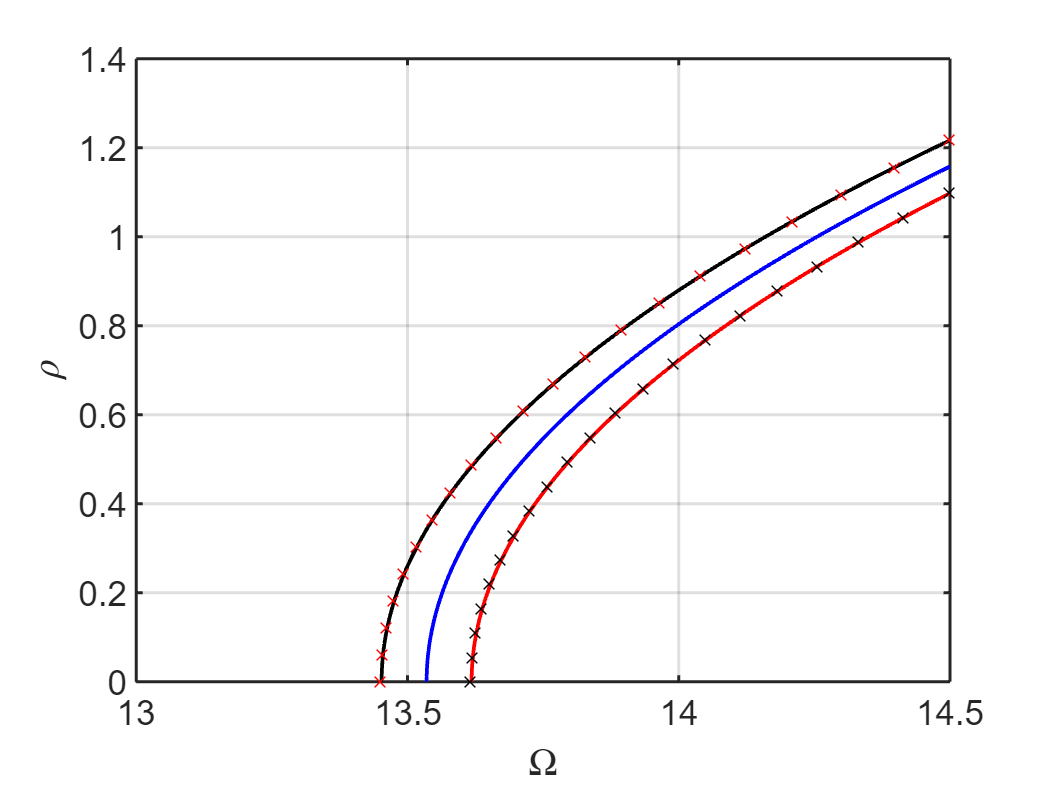

figure(figrho); hold on
plot(bbp1{1}.om(1:5:end),bbp1{1}.rho(1:5:end),'kx')
plot(bbp3{1}.om(1:5:end),bbp3{1}.rho(1:5:end),'rx')

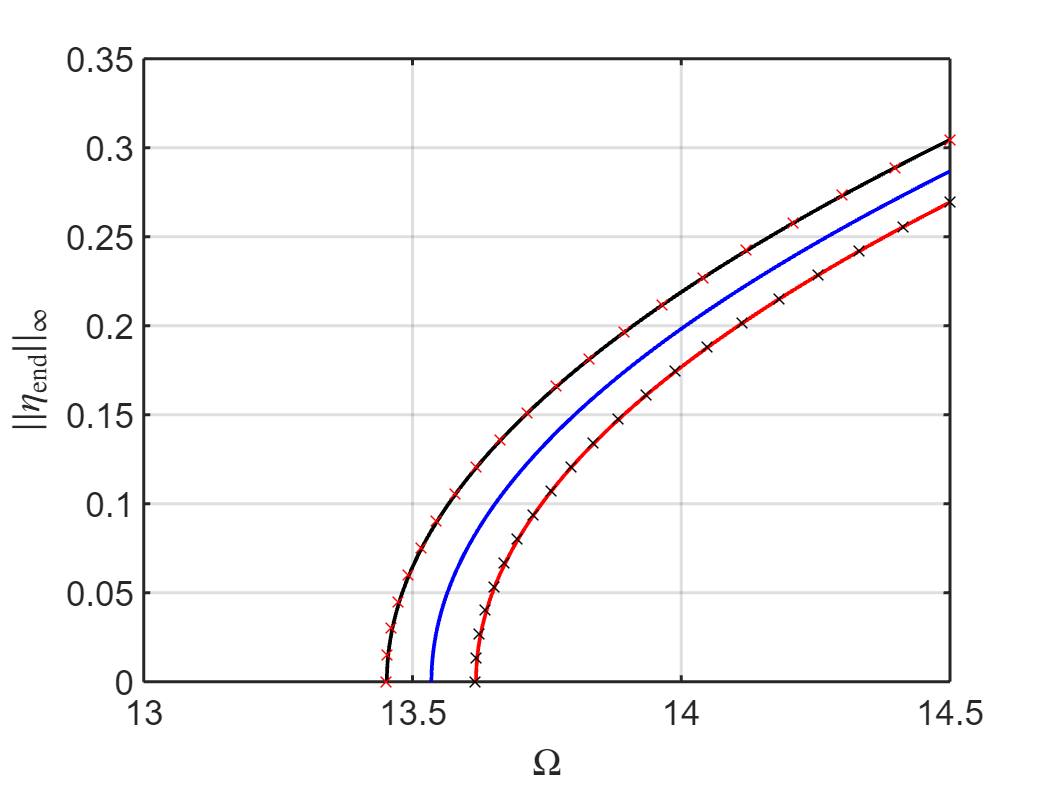

figure(figz); hold on
plot(bbp1{1}.om(1:5:end),bbp1{1}.ampLinf(1,1:5:end),'kx')
plot(bbp3{1}.om(1:5:end),bbp3{1}.ampLinf(1,1:5:end),'rx')

### Perturbed limit cycles

- **Compute perturbed limit cycles**

% pfracs = [-0.05 0 0.1];
% pidx   = 1; pfracs = [-0.015 0 0.015]*flowspeed;
% pidx   = 2; pfracs = [-0.04 0 0.04]*beta;
pidx   = 3; pfracs = [-1 0 1]*alpha;
pLCs = S.LC_sensitivity(We,Re,DW,DR,1:2*nmodes,pidx,pfracs);
LC1 = obs(pLCs{1}.zout); LC2 = obs(pLCs{2}.zout); LC3 = obs(pLCs{3}.zout);

- **Plot the obtained limit cycles**

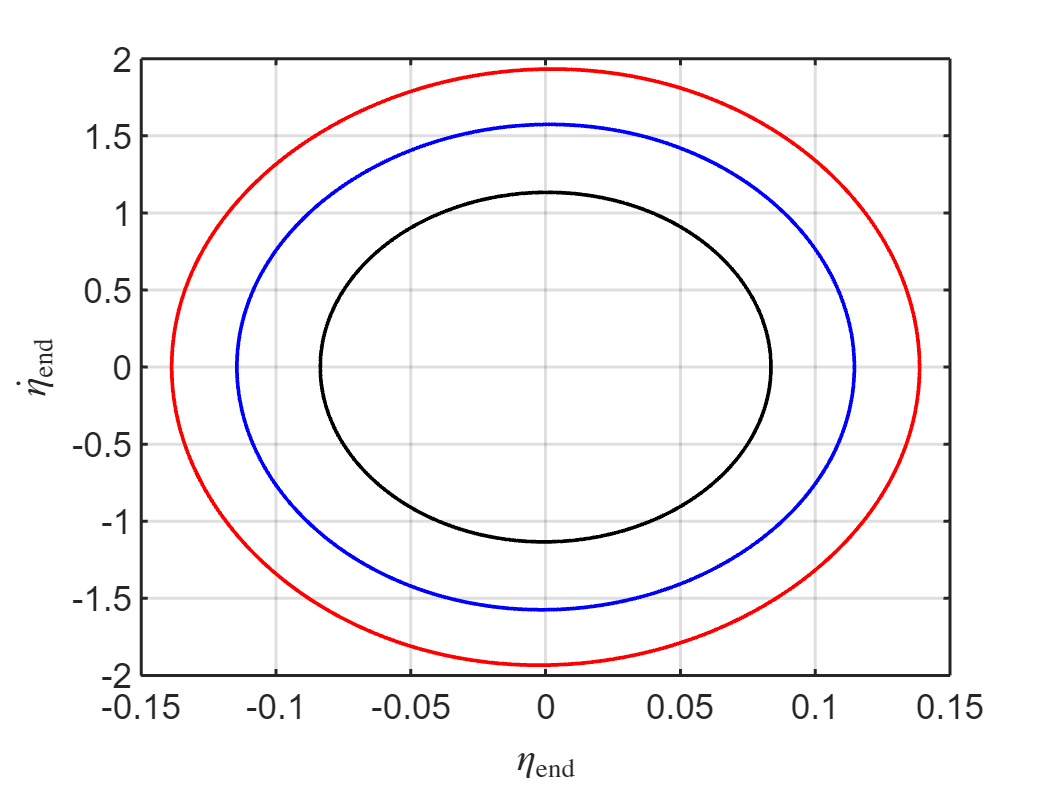

figure; hold on
plot(LC1(1,:),LC1(2,:),'r-','LineWidth',1.5);
plot(LC2(1,:),LC2(2,:),'b-','LineWidth',1.5);
plot(LC3(1,:),LC3(2,:),'k-','LineWidth',1.5);
grid on; box on; 
xlabel('$\eta_\mathrm{end}$','FontSize',14,'Interpreter','latex');
ylabel('$\dot{\eta}_\mathrm{end}$','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',14);
set(gca,'LineWidth',1.2);

figlc = gcf;

- **Direct computation - for the purpose of validation**

% bbp1 = comp_lc(nmodes,flowspeed+pfracs(1),beta,alpha,lo);
% bbp3 = comp_lc(nmodes,flowspeed+pfracs(3),beta,alpha,lo);
% bbp1 = comp_lc(nmodes,flowspeed,beta+pfracs(1),alpha,lo);
% bbp3 = comp_lc(nmodes,flowspeed,beta+pfracs(3),alpha,lo);
bbp1 = comp_lc(nmodes,flowspeed,beta,alpha+pfracs(1),lo);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0033 + 0.1362i
   0.0033 - 0.1362i
  -0.0484 + 1.1129i
  -0.0484 - 1.1129i
  -0.0498 + 0.4900i
  -0.0498 - 0.4900i
  -0.1107 + 0.0302i
  -0.1107 - 0.0302i



ans =    1.0000 + 0.0000i  -0.0000 + 0.0000i
  -0.0000 - 0.0000i   1.0000 - 0.0000i


ans = 1.0e-11 *

  -0.0987 + 0.1400i  -0.0016 - 0.0597i
  -0.0016 + 0.0597i  -0.0987 - 0.1400i


sigma_out = -33
sigma_in = -33

 second order explict solution 


bbp3 = comp_lc(nmodes,flowspeed,beta,alpha+pfracs(3),lo);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0012 + 0.1345i
   0.0012 - 0.1345i
  -0.0875 + 0.4843i
  -0.0875 - 0.4843i
  -0.1129 + 0.0281i
  -0.1129 - 0.0281i
  -0.1957 + 1.0962i
  -0.1957 - 1.0962i



ans =    1.0000 + 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 - 0.0000i


ans = 1.0e-12 *

  -0.1004 + 0.0906i  -0.0062 + 0.0391i
  -0.0062 - 0.0391i  -0.1004 - 0.0906i


sigma_out = -163
sigma_in = -163

 second order explict solution 


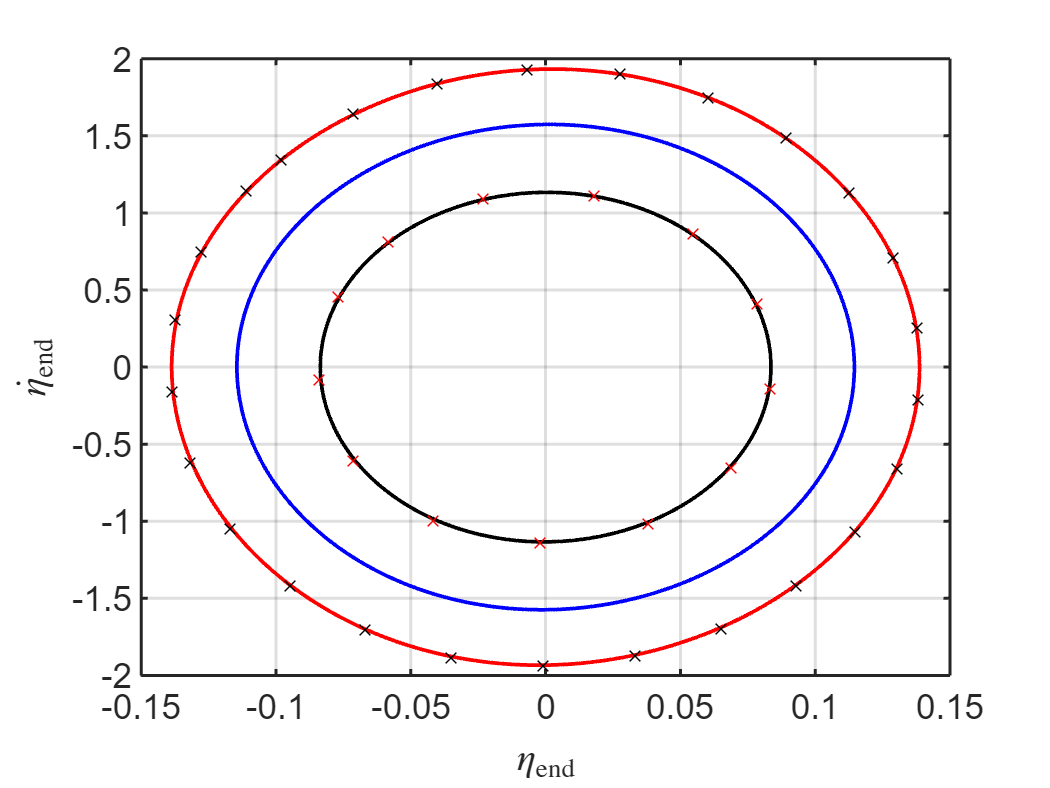

LCp1 = obs(bbp1{1}.zout); LCp3 = obs(bbp3{1}.zout);
figure(figlc); hold on
plot(LCp1(1,1:50:end),LCp1(2,1:50:end),'kx');
plot(LCp3(1,1:100:end),LCp3(2,1:100:end),'rx');

#### Relative difference to determine the sign of the derivative of rho^\ast

-real(Dlamd)*real(Re.r21)+real(Dr21)*real(Re.Lambda_E)

ans =     2.2022
  -24.8132
 -109.6452


## *Forced vibration*

### Sensitivity of forced periodic response

optdof = [1 2 3 4]; Q = phiend*phiend'; epsilon = 0.1;
[frce,dfrce] = S.po_sensitivity(We,Re,DW,DR,optdof,Q,epsilon);

#### Validation via central finite difference

- with respect to $u$

% compute perturbed periodic orbit
uE  = DS.spectrum.W(:,1);
psi = conj(uE(1:DS.n)); lo = (2*DS.spectrum.Lambda(1)*M+C).'*psi;
du  = 0.0001*flowspeed; % 0.001 is default
frc_up = comp_frc(nmodes,flowspeed+du,beta,alpha,lo,Om,Q,epsilon);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0022 + 0.1354i
   0.0022 - 0.1354i
  -0.0687 + 0.4875i
  -0.0687 - 0.4875i
  -0.1118 + 0.0292i
  -0.1118 - 0.0292i
  -0.1221 + 1.1069i
  -0.1221 - 1.1069i



ans =    1.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


ans = 1.0e-12 *

  -0.9210 - 0.3855i  -0.4943 + 0.3606i
  -0.4943 - 0.3606i  -0.9210 + 0.3855i


sigma_out = -54
sigma_in = -54

 second order explict solution 


frc_um = comp_frc(nmodes,flowspeed-du,beta,alpha,lo,Om,Q,epsilon);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0022 + 0.1354i
   0.0022 - 0.1354i
  -0.0687 + 0.4875i
  -0.0687 - 0.4875i
  -0.1118 + 0.0292i
  -0.1118 - 0.0292i
  -0.1221 + 1.1070i
  -0.1221 - 1.1070i



ans =    1.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


ans = 1.0e-12 *

  -0.9810 - 0.3144i  -0.5691 + 0.3837i
  -0.5691 - 0.3837i  -0.9810 + 0.3144i


sigma_out = -55
sigma_in = -55

 second order explict solution 


% calculate derivatives
drho_du = (frc_up.rho - frc_um.rho)/(2*du);
dth_du  = (frc_up.th - frc_um.th)/(2*du);
damp_du = (frc_up.amp - frc_um.amp)/(2*du);
drhomax_du = (frc_up.rhomax-frc_um.rhomax)/(2*du);
dommax_du  = (frc_up.Ommax-frc_um.Ommax)/(2*du);
% compute relative or absolute errors and print them
fprintf('relative error for drho_du is %d\n', abs((dfrce.Drho(1)-drho_du)/dfrce.Drho(1))); 

relative error for drho_du is 7.522725e-05


fprintf('relative error for dth_du is %d\n', abs((dfrce.Dth(1)-dth_du)/dfrce.Dth(1))); 

relative error for dth_du is 1.551042e-04


fprintf('relative error for damp_du is %d\n', abs((dfrce.Damp(1)-damp_du)/dfrce.Damp(1)));

relative error for damp_du is 7.573741e-05


fprintf('realtive error for drhomax_du is %d\n', abs((dfrce.Drhomax(1)-drhomax_du)/dfrce.Drhomax(1)));

realtive error for drhomax_du is 3.125112e-04


fprintf('relative error for dommax_du is %d\n', abs((dfrce.DOmmax(1)-dommax_du)/dfrce.DOmmax(1)));

relative error for dommax_du is 3.182335e-04


% NOTE!!! The last one converges slowly

- with respect to $\beta$

% compute perturbed periodic orbit
dbe = 0.0001*beta; 
frc_bep = comp_frc(nmodes,flowspeed,beta+dbe,alpha,lo,Om,Q,epsilon);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0022 + 0.1354i
   0.0022 - 0.1354i
  -0.0687 + 0.4875i
  -0.0687 - 0.4875i
  -0.1118 + 0.0292i
  -0.1118 - 0.0292i
  -0.1221 + 1.1069i
  -0.1221 - 1.1069i



ans =    1.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


ans = 1.0e-11 *

  -0.1001 - 0.0286i  -0.0490 + 0.0340i
  -0.0490 - 0.0340i  -0.1001 + 0.0286i


sigma_out = -55
sigma_in = -55

 second order explict solution 


frc_bem = comp_frc(nmodes,flowspeed,beta-dbe,alpha,lo,Om,Q,epsilon);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0022 + 0.1354i
   0.0022 - 0.1354i
  -0.0687 + 0.4875i
  -0.0687 - 0.4875i
  -0.1118 + 0.0292i
  -0.1118 - 0.0292i
  -0.1221 + 1.1069i
  -0.1221 - 1.1069i



ans =    1.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


ans = 1.0e-11 *

  -0.1052 - 0.0364i  -0.0523 + 0.0334i
  -0.0523 - 0.0334i  -0.1052 + 0.0364i


sigma_out = -54
sigma_in = -54

 second order explict solution 


% calculate derivatives
drho_dbe = (frc_bep.rho - frc_bem.rho)/(2*dbe);
dth_dbe  = (frc_bep.th - frc_bem.th)/(2*dbe);
damp_dbe = (frc_bep.amp - frc_bem.amp)/(2*dbe);
drhomax_dbe = (frc_bep.rhomax-frc_bem.rhomax)/(2*dbe);
dommax_dbe  = (frc_bep.Ommax-frc_bem.Ommax)/(2*dbe);
% compute relative or absolute errors and print them
fprintf('relative error for drho_dbe is %d\n', abs((dfrce.Drho(2)-drho_dbe)/dfrce.Drho(2))); 

relative error for drho_dbe is 1.370629e-05


fprintf('relative error for dth_dbe is %d\n', abs((dfrce.Dth(2)-dth_dbe)/dfrce.Dth(2))); 

relative error for dth_dbe is 2.830312e-05


fprintf('relative error for damp_dbe is %d\n', abs((dfrce.Damp(2)-damp_dbe)/dfrce.Damp(2)));

relative error for damp_dbe is 1.378075e-05


fprintf('realtive error for drhomax_dbe is %d\n', abs((dfrce.Drhomax(2)-drhomax_dbe)/dfrce.Drhomax(2)));

realtive error for drhomax_dbe is 4.667782e-05


fprintf('relative error for dommax_dbe is %d\n', abs((dfrce.DOmmax(2)-dommax_dbe)/dfrce.DOmmax(2)));

relative error for dommax_dbe is 5.744166e-05


- with respect to $\alpha$

% compute perturbed periodic orbit
dal = 0.01*alpha; 
frc_alp = comp_frc(nmodes,flowspeed,beta,alpha+dal,lo,Om,Q,epsilon);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0022 + 0.1353i
   0.0022 - 0.1353i
  -0.0689 + 0.4875i
  -0.0689 - 0.4875i
  -0.1118 + 0.0292i
  -0.1118 - 0.0292i
  -0.1228 + 1.1069i
  -0.1228 - 1.1069i



ans =    1.0000 + 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 - 0.0000i


ans = 1.0e-11 *

  -0.1109 - 0.0300i  -0.0515 + 0.0331i
  -0.0515 - 0.0331i  -0.1109 + 0.0300i


sigma_out = -55
sigma_in = -55

 second order explict solution 


frc_alm = comp_frc(nmodes,flowspeed,beta,alpha-dal,lo,Om,Q,epsilon);

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0022 + 0.1354i
   0.0022 - 0.1354i
  -0.0685 + 0.4875i
  -0.0685 - 0.4875i
  -0.1118 + 0.0292i
  -0.1118 - 0.0292i
  -0.1213 + 1.1070i
  -0.1213 - 1.1070i



ans =    1.0000 + 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


ans = 1.0e-12 *

  -0.8240 - 0.7230i  -0.4956 + 0.3304i
  -0.4956 - 0.3304i  -0.8240 + 0.7230i


sigma_out = -54
sigma_in = -54

 second order explict solution 


% calculate derivatives
drho_dal = (frc_alp.rho - frc_alm.rho)/(2*dal);
dth_dal  = (frc_alp.th - frc_alm.th)/(2*dal);
damp_dal = (frc_alp.amp - frc_alm.amp)/(2*dal);
drhomax_dal = (frc_alp.rhomax-frc_alm.rhomax)/(2*dal);
dommax_dal  = (frc_alp.Ommax-frc_alm.Ommax)/(2*dal);
% compute relative or absolute errors and print them
fprintf('relative error for drho_dal is %d\n', abs((dfrce.Drho(3)-drho_dal)/dfrce.Drho(3))); 

relative error for drho_dal is 1.380536e-04


fprintf('relative error for dth_dal is %d\n', abs((dfrce.Dth(3)-dth_dal)/dfrce.Dth(3))); 

relative error for dth_dal is 4.845557e-04


fprintf('relative error for damp_dal is %d\n', abs((dfrce.Damp(3)-damp_dal)/dfrce.Damp(3)));

relative error for damp_dal is 1.385926e-04


fprintf('realtive error for drhomax_dal is %d\n', abs((dfrce.Drhomax(3)-drhomax_dal)/dfrce.Drhomax(3)));

realtive error for drhomax_dal is 2.080183e-04


fprintf('relative error for dommax_dal is %d\n', abs((dfrce.DOmmax(3)-dommax_dal)/dfrce.DOmmax(3)));

relative error for dommax_dal is 1.606523e-04


### Peturbed FRCs

% pidx   = 1; pfracs = [-0.002 0 0.002]*flowspeed;
% pidx   = 2; pfracs = [-0.006 0 0.006]*beta;
pidx   = 3; pfracs = [-0.2 0 0.2]*alpha;
set(S.Options,'contribNonAuto',false);
pFRCs = S.FRC_sensitivity(We,Re,DW,DR,optdof,Q,epsilon,freqRange,pidx,pfracs,'isola');

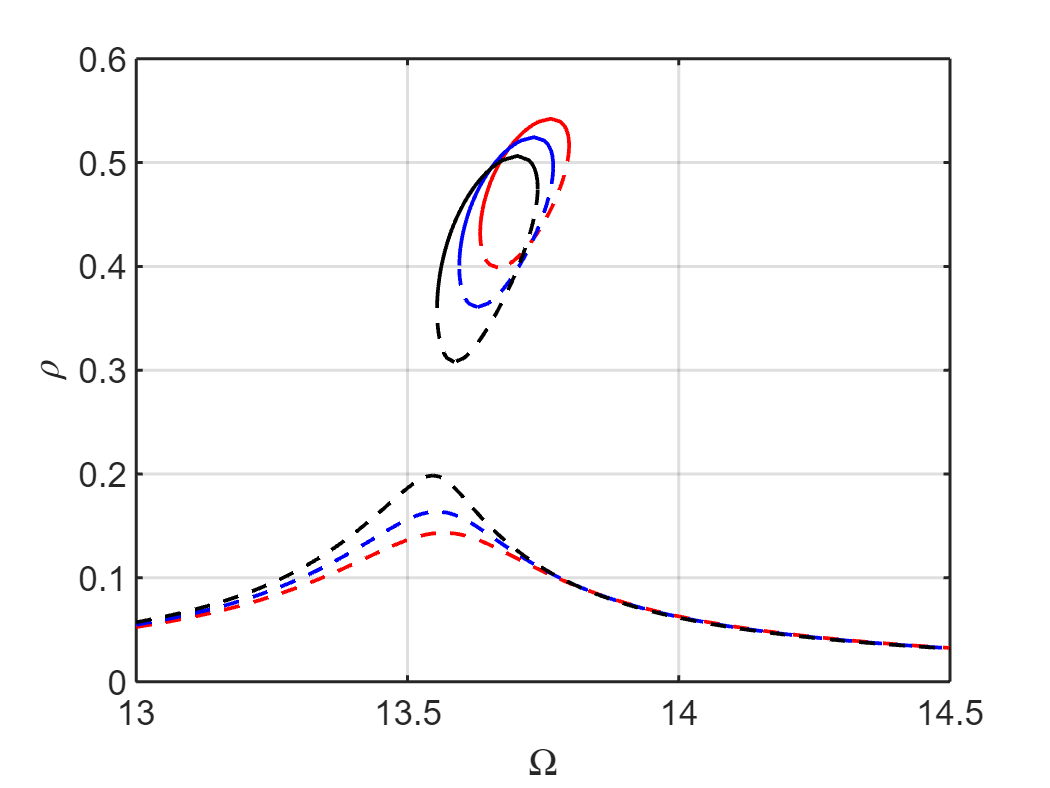

% plot FRCs with isolas
ST1 = cell(2,1);
ST1{1} = {'r--','LineWidth',1.5}; % unstable
ST1{2} = {'r-','LineWidth',1.5};  % stable
ST2 = cell(2,1);
ST2{1} = {'b--','LineWidth',1.5}; % unstable
ST2{2} = {'b-','LineWidth',1.5};  % stable
ST3 = cell(2,1);
ST3{1} = {'k--','LineWidth',1.5}; % unstable
ST3{2} = {'k-','LineWidth',1.5};  % stable
figure; hold on
plot_stab_lines(pFRCs{1}{1}.om,pFRCs{1}{1}.rho,pFRCs{1}{1}.st,ST1);
plot_stab_lines(pFRCs{1}{2}.om,pFRCs{1}{2}.rho,pFRCs{1}{2}.st,ST1);
plot_stab_lines(pFRCs{2}{1}.om,pFRCs{2}{1}.rho,pFRCs{2}{1}.st,ST2);
plot_stab_lines(pFRCs{2}{2}.om,pFRCs{2}{2}.rho,pFRCs{2}{2}.st,ST2);
plot_stab_lines(pFRCs{3}{1}.om,pFRCs{3}{1}.rho,pFRCs{3}{1}.st,ST3);
plot_stab_lines(pFRCs{3}{2}.om,pFRCs{3}{2}.rho,pFRCs{3}{2}.st,ST3);
xlim(freqRange); grid on; box on
xlabel('$\Omega$','FontSize',14,'Interpreter','latex');
ylabel('$\rho$','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',14); set(gca,'LineWidth',1.2);

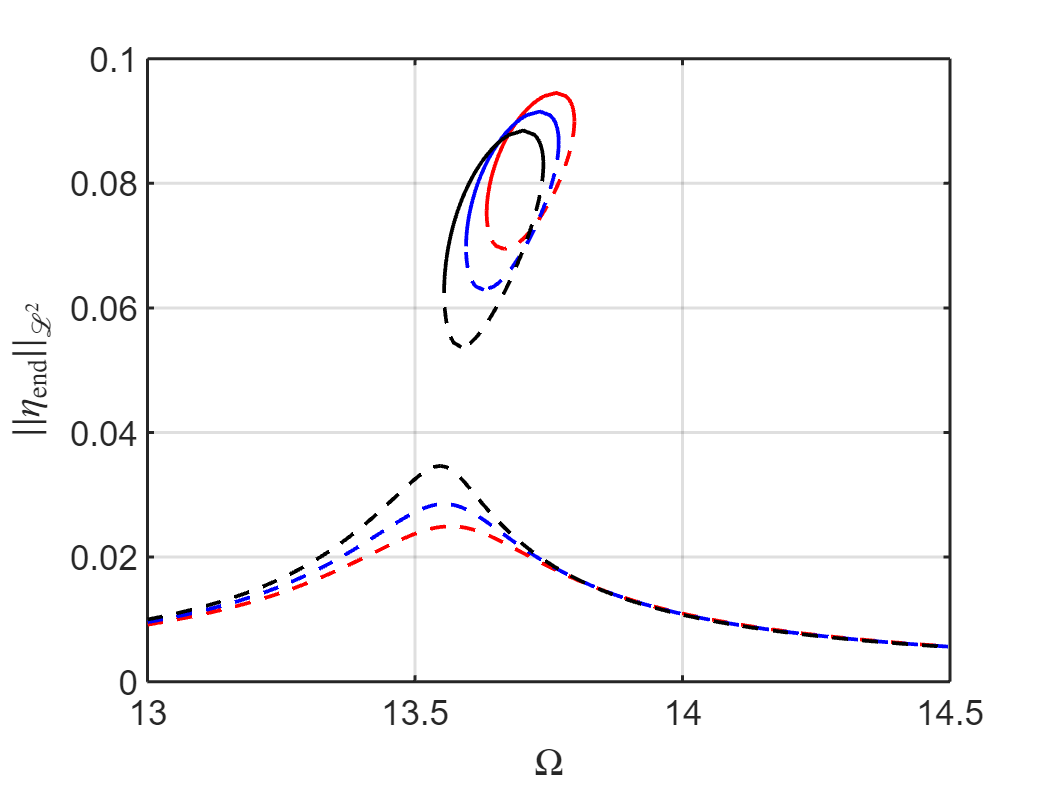

figfrcrho = gcf;
figure; hold on
plot_stab_lines(pFRCs{1}{1}.om,pFRCs{1}{1}.ampL2,pFRCs{1}{1}.st,ST1);
plot_stab_lines(pFRCs{1}{2}.om,pFRCs{1}{2}.ampL2,pFRCs{1}{2}.st,ST1);
plot_stab_lines(pFRCs{2}{1}.om,pFRCs{2}{1}.ampL2,pFRCs{2}{1}.st,ST2);
plot_stab_lines(pFRCs{2}{2}.om,pFRCs{2}{2}.ampL2,pFRCs{2}{2}.st,ST2);
plot_stab_lines(pFRCs{3}{1}.om,pFRCs{3}{1}.ampL2,pFRCs{3}{1}.st,ST3);
plot_stab_lines(pFRCs{3}{2}.om,pFRCs{3}{2}.ampL2,pFRCs{3}{2}.st,ST3);
xlim(freqRange); grid on; box on
xlabel('$\Omega$','FontSize',14,'Interpreter','latex');
ylabel('$||\eta_\mathrm{end}||_{\mathcal{L}^2}$','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',14); set(gca,'LineWidth',1.2);

figfrcamp = gcf;

**Direct computation - for the purpose of validation**

% [~,frcp1] = comp_frc(nmodes,flowspeed+pfracs(1),beta,alpha,lo,Om,Q,epsilon,freqRange,'isola');
% [~,frcp3] = comp_frc(nmodes,flowspeed+pfracs(3),beta,alpha,lo,Om,Q,epsilon,freqRange,'isola');
% [~,frcp1] = comp_frc(nmodes,flowspeed,beta+pfracs(1),alpha,lo,Om,Q,epsilon,freqRange,'isola');
% [~,frcp3] = comp_frc(nmodes,flowspeed,beta+pfracs(3),alpha,lo,Om,Q,epsilon,freqRange,'isola');
[~,frcp1] = comp_frc(nmodes,flowspeed,beta,alpha+pfracs(1),lo,Om,Q,epsilon,freqRange,'isola');

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0024 + 0.1355i
   0.0024 - 0.1355i
  -0.0649 + 0.4880i
  -0.0649 - 0.4880i
  -0.1073 + 1.1085i
  -0.1073 - 1.1085i
  -0.1116 + 0.0294i
  -0.1116 - 0.0294i



ans =    1.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


ans = 1.0e-11 *

  -0.0179 - 0.1195i  -0.0157 + 0.0092i
  -0.0157 - 0.0092i  -0.0179 + 0.1195i


sigma_out = -45
sigma_in = -45

 second order explict solution 


[~,frcp3] = comp_frc(nmodes,flowspeed,beta,alpha+pfracs(3),lo,Om,Q,epsilon,freqRange,'isola');

Getting linear and nonlinearity coefficients
Loaded coefficients from storage

 The first 8 eigenvalues are given as 
   1.0e+02 *

   0.0020 + 0.1352i
   0.0020 - 0.1352i
  -0.0724 + 0.4869i
  -0.0724 - 0.4869i
  -0.1120 + 0.0290i
  -0.1120 - 0.0290i
  -0.1368 + 1.1052i
  -0.1368 - 1.1052i



ans =    1.0000 - 0.0000i  -0.0000 - 0.0000i
  -0.0000 + 0.0000i   1.0000 + 0.0000i


ans = 1.0e-11 *

  -0.0739 + 0.1265i  -0.0171 + 0.0093i
  -0.0171 - 0.0093i  -0.0739 - 0.1265i


sigma_out = -67
sigma_in = -67

 second order explict solution 


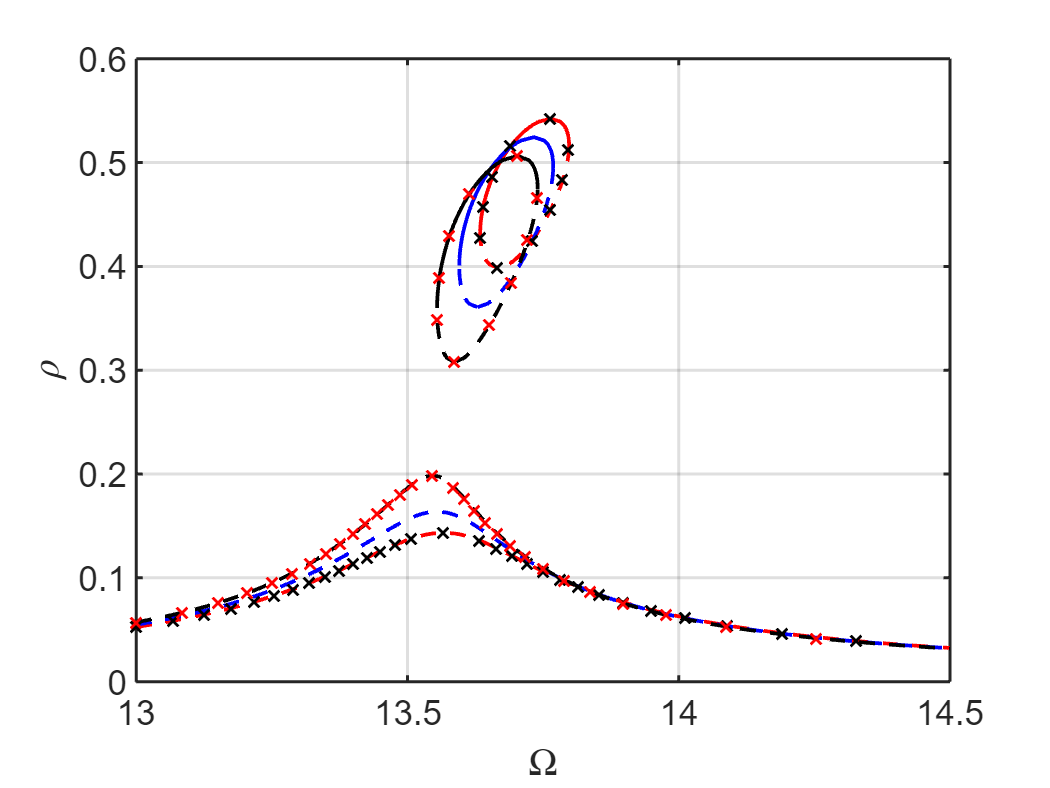

figure(figfrcrho); hold on
plot(frcp1{1}{1}.om(1:10:end),frcp1{1}{1}.rho(1:10:end),'kx','LineWidth',1)
plot(frcp1{1}{2}.om(1:10:end),frcp1{1}{2}.rho(1:10:end),'kx','LineWidth',1)
plot(frcp3{1}{1}.om(1:10:end),frcp3{1}{1}.rho(1:10:end),'rx','LineWidth',1)
plot(frcp3{1}{2}.om(1:10:end),frcp3{1}{2}.rho(1:10:end),'rx','LineWidth',1)

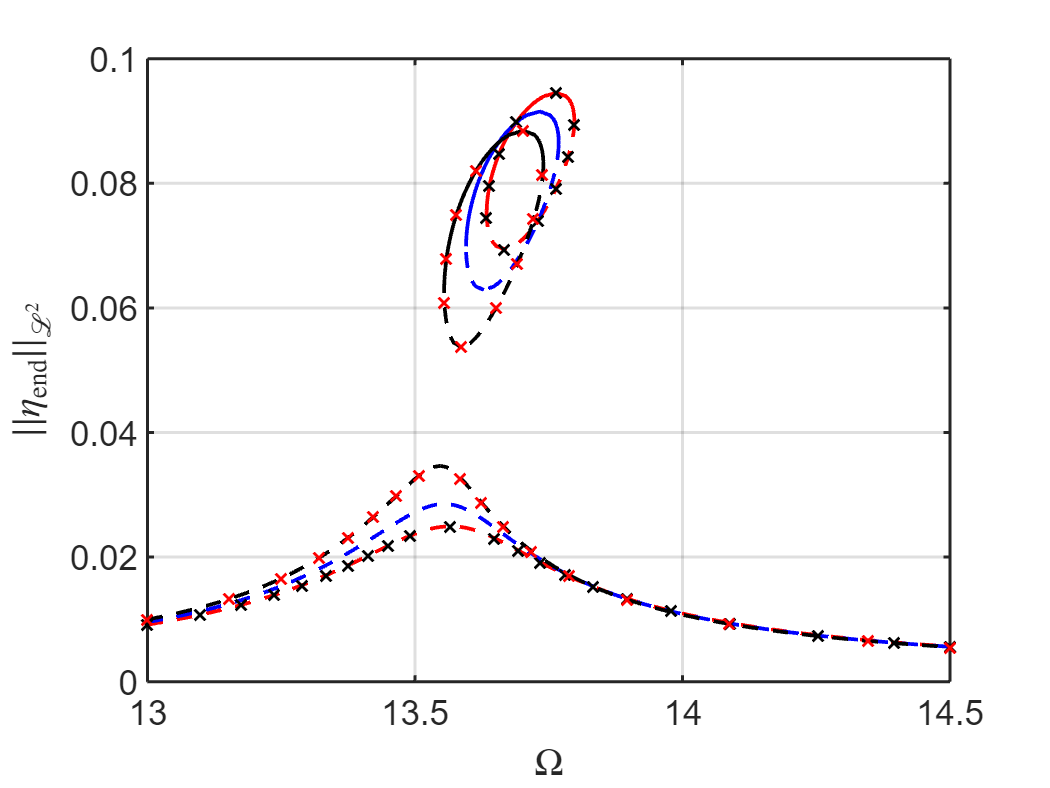

figure(figfrcamp); hold on
idx1 = [1:15:numel(frcp1{1}{1}.om),numel(frcp1{1}{1}.om)-5,numel(frcp1{1}{1}.om)];
idx3 = [1:20:numel(frcp3{1}{1}.om),numel(frcp3{1}{1}.om)-5,numel(frcp3{1}{1}.om)];
plot(frcp1{1}{1}.om(idx1),frcp1{1}{1}.ampL2(idx1),'kx','LineWidth',1)
plot(frcp1{1}{2}.om(1:10:end),frcp1{1}{2}.ampL2(1:10:end),'kx','LineWidth',1)
plot(frcp3{1}{1}.om(idx3),frcp3{1}{1}.ampL2(idx3),'rx','LineWidth',1)
plot(frcp3{1}{2}.om(1:10:end),frcp3{1}{2}.ampL2(1:10:end),'rx','LineWidth',1)